V0=1;
gamma=2*pi*1i;
z = -2:0.02:0;

GAMMA=exp(1i*pi/4);
Z0=100;
[Vs,Is] = linephasor(V0,GAMMA,gamma,Z0,z);
Vs = abs(Vs);
Is = 100*abs(Is);
for z=0
    ratio = 100*Vs/Is
    z = -2:0.02:0;
end

ratio = 100.0000

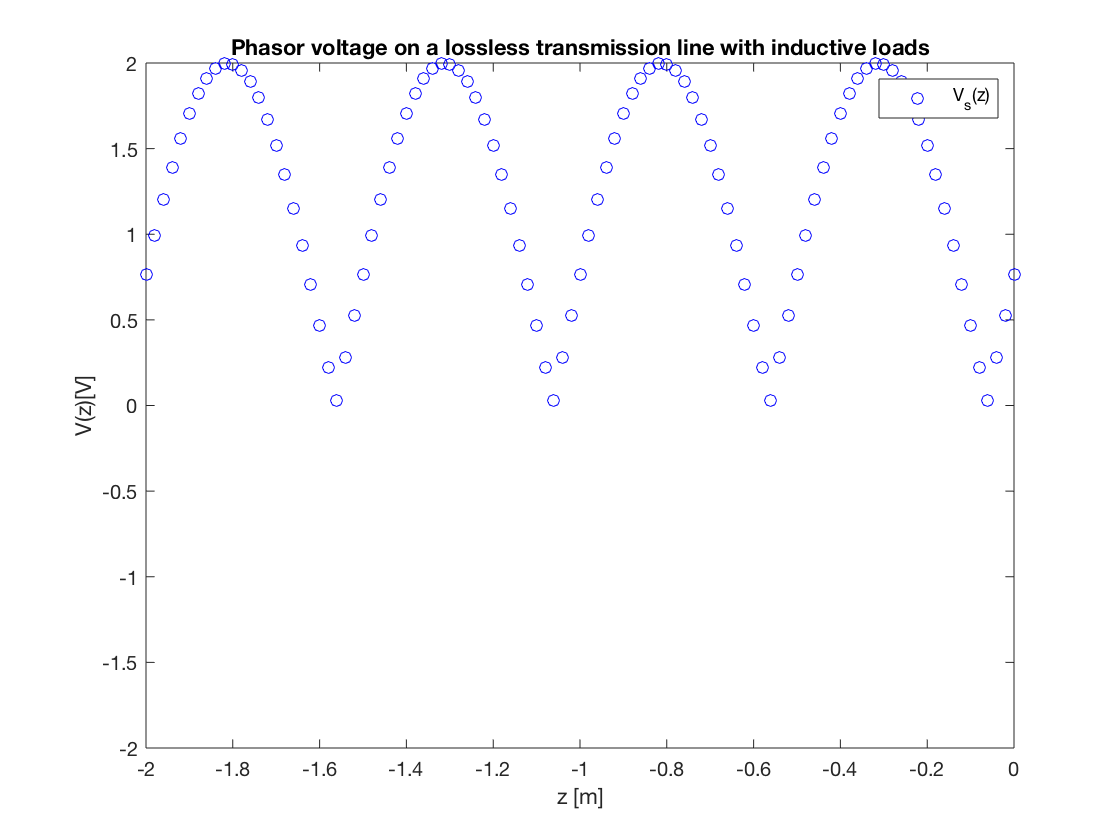

plot(z,Vs,'bo');
xlabel('z [m]');
ylabel('V(z)[V]');
title('Phasor voltage on a lossless transmission line with inductive loads');
legend('V_s(z)');
axis([-2 0 -2 2]);

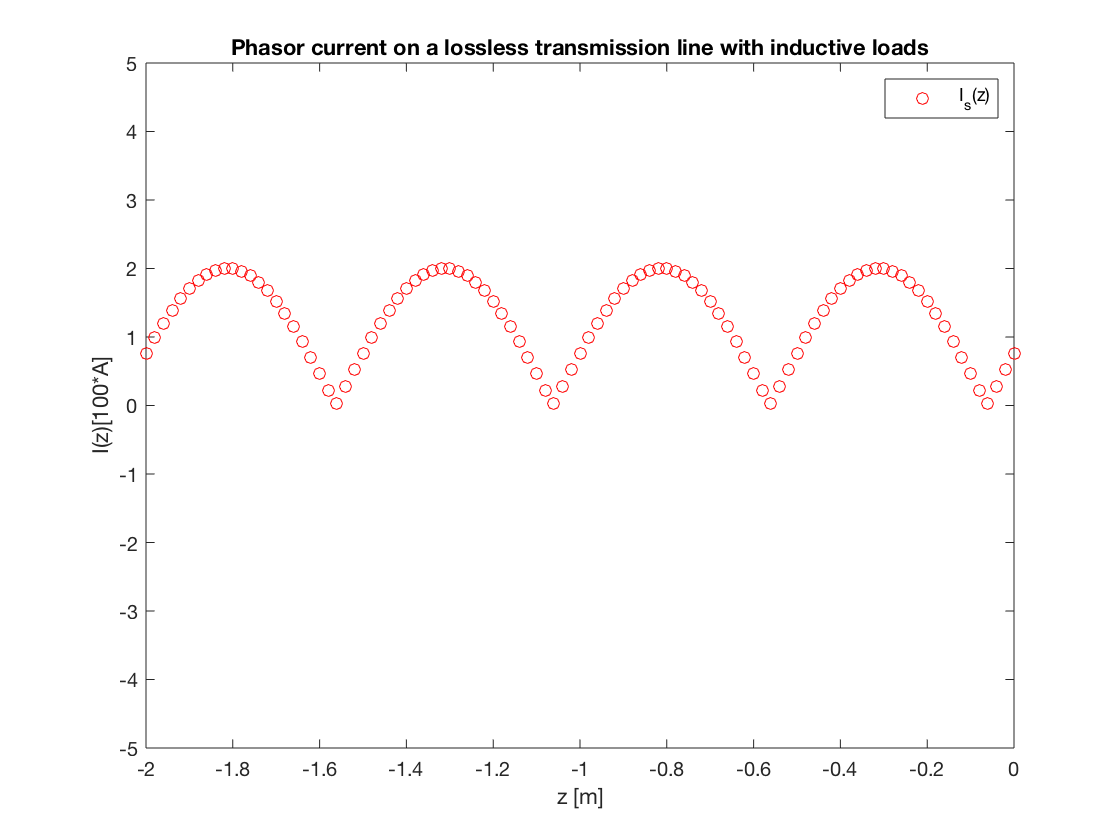

plot(z,Is,'ro');
xlabel('z [m]');
ylabel('I(z)[100*A]');
title('Phasor current on a lossless transmission line with inductive loads');
legend('I_s(z)');
axis([-2 0 -5 5]);


GAMMA=exp(1i*pi/2);
Z0=100;
[Vs,Is] = linephasor(V0,GAMMA,gamma,Z0,z);
Vs = abs(Vs);
Is = 100*abs(Is);
for z=0
    ratio = 100*Vs/Is
    z = -2:0.02:0;
end

ratio = 100

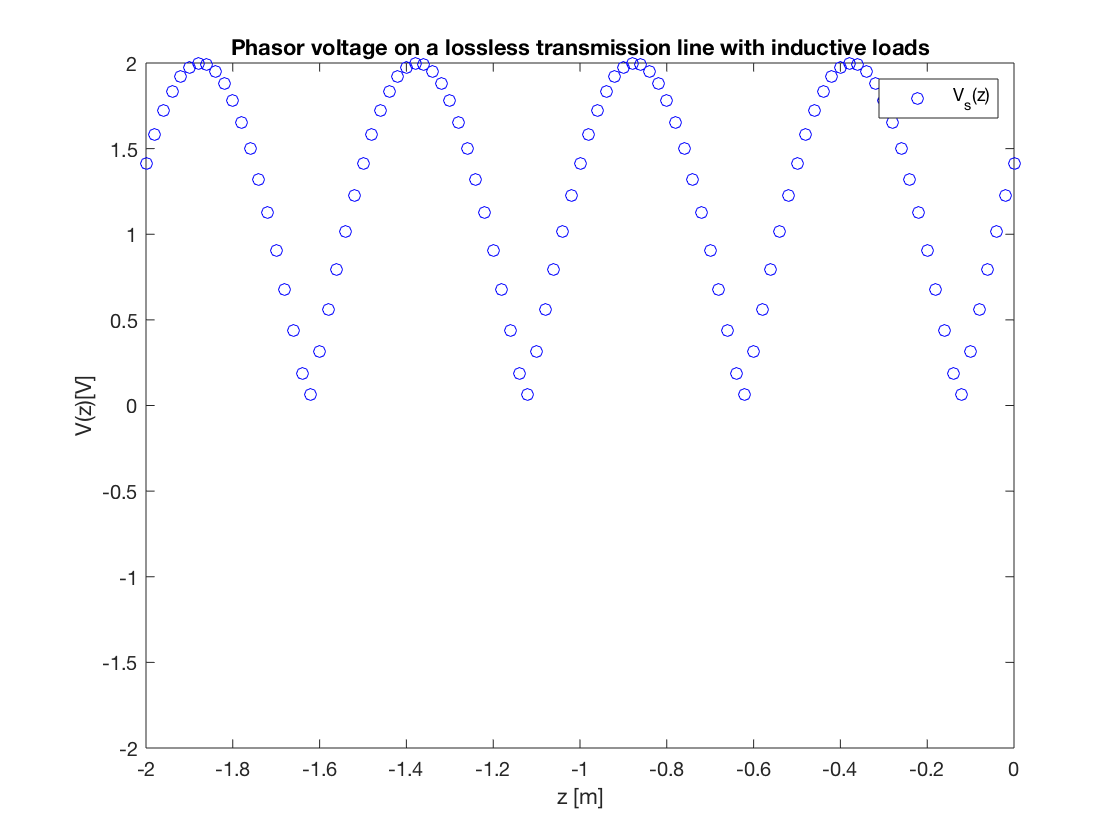

plot(z,Vs,'bo');
xlabel('z [m]');
ylabel('V(z)[V]');
title('Phasor voltage on a lossless transmission line with inductive loads');
legend('V_s(z)');
axis([-2 0 -2 2]);

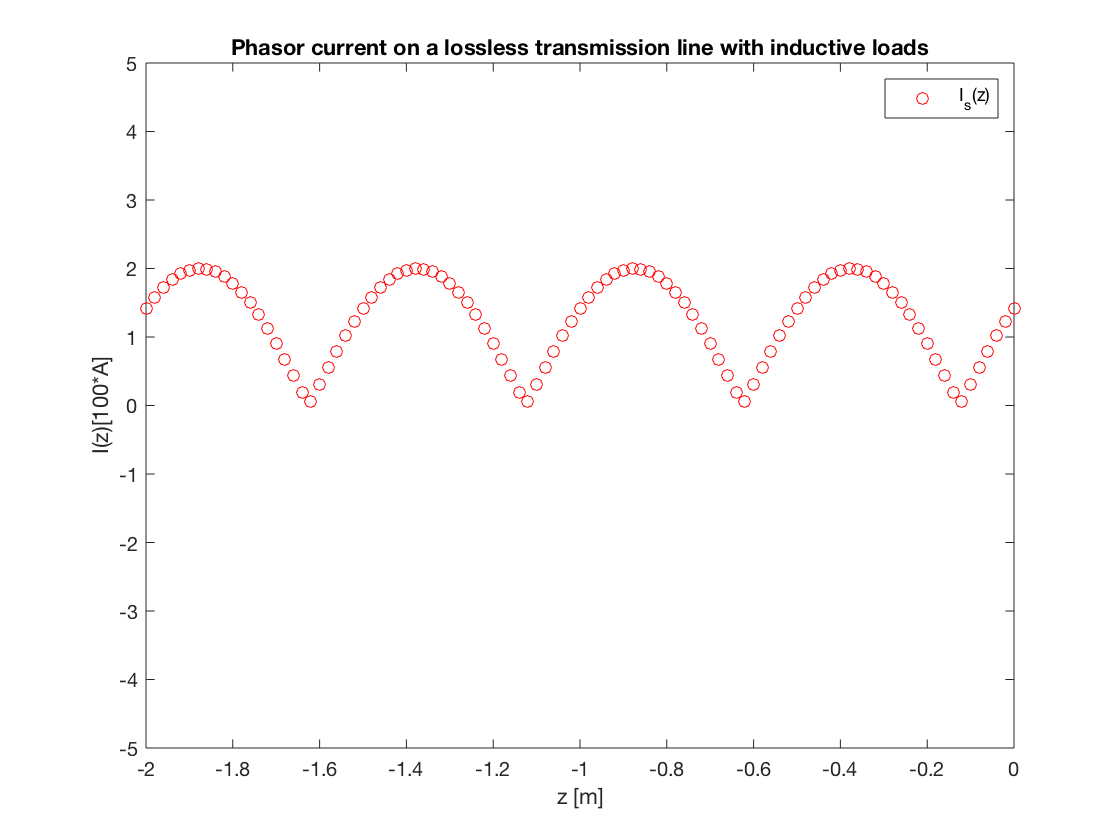

plot(z,Is,'ro');
xlabel('z [m]');
ylabel('I(z)[100*A]');
title('Phasor current on a lossless transmission line with inductive loads');
legend('I_s(z)');
axis([-2 0 -5 5]);


GAMMA=exp(3i*pi/4);
Z0=100;
[Vs,Is] = linephasor(V0,GAMMA,gamma,Z0,z);
Vs = abs(Vs);
Is = 100*abs(Is);
for z=0
    ratio = 100*Vs/Is
    z = -2:0.02:0;
end

ratio = 100.0000

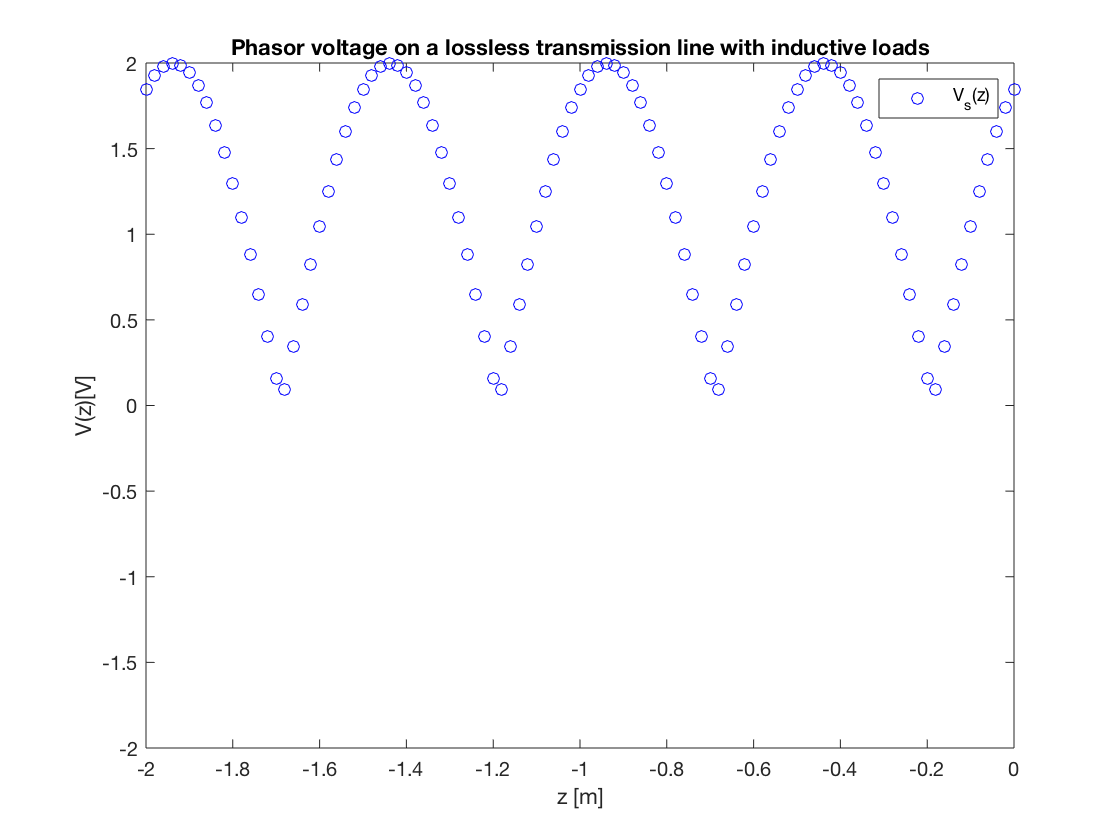

plot(z,Vs,'bo');
xlabel('z [m]');
ylabel('V(z)[V]');
title('Phasor voltage on a lossless transmission line with inductive loads');
legend('V_s(z)');
axis([-2 0 -2 2]);

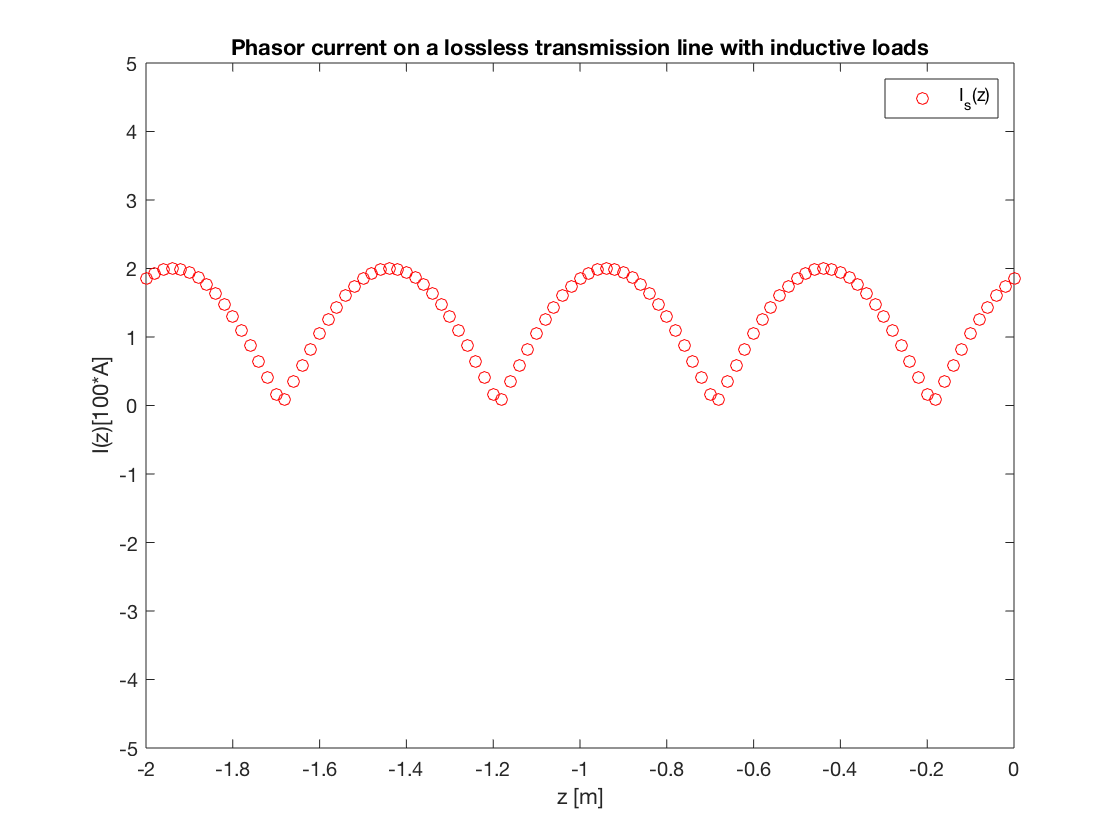

plot(z,Is,'ro');
xlabel('z [m]');
ylabel('I(z)[100*A]');
title('Phasor current on a lossless transmission line with inductive loads');
legend('I_s(z)');
axis([-2 0 -5 5]);


GAMMA=exp(1i*pi);
Z0=100;
[Vs,Is] = linephasor(V0,GAMMA,gamma,Z0,z);
Vs = abs(Vs);
Is = 100*abs(Is);
for z=0
    ratio = 100*Vs/Is
    z = -2:0.02:0;
end

ratio = 100

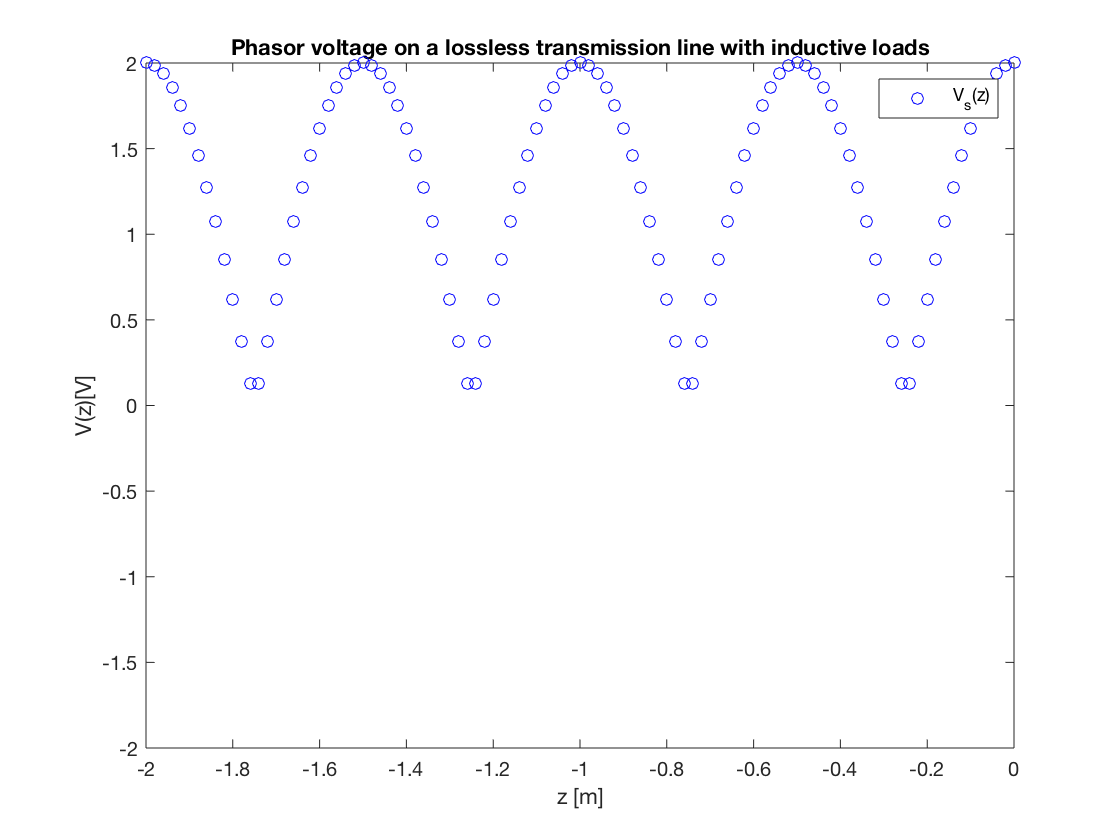

plot(z,Vs,'bo');
xlabel('z [m]');
ylabel('V(z)[V]');
title('Phasor voltage on a lossless transmission line with inductive loads');
legend('V_s(z)');
axis([-2 0 -2 2]);

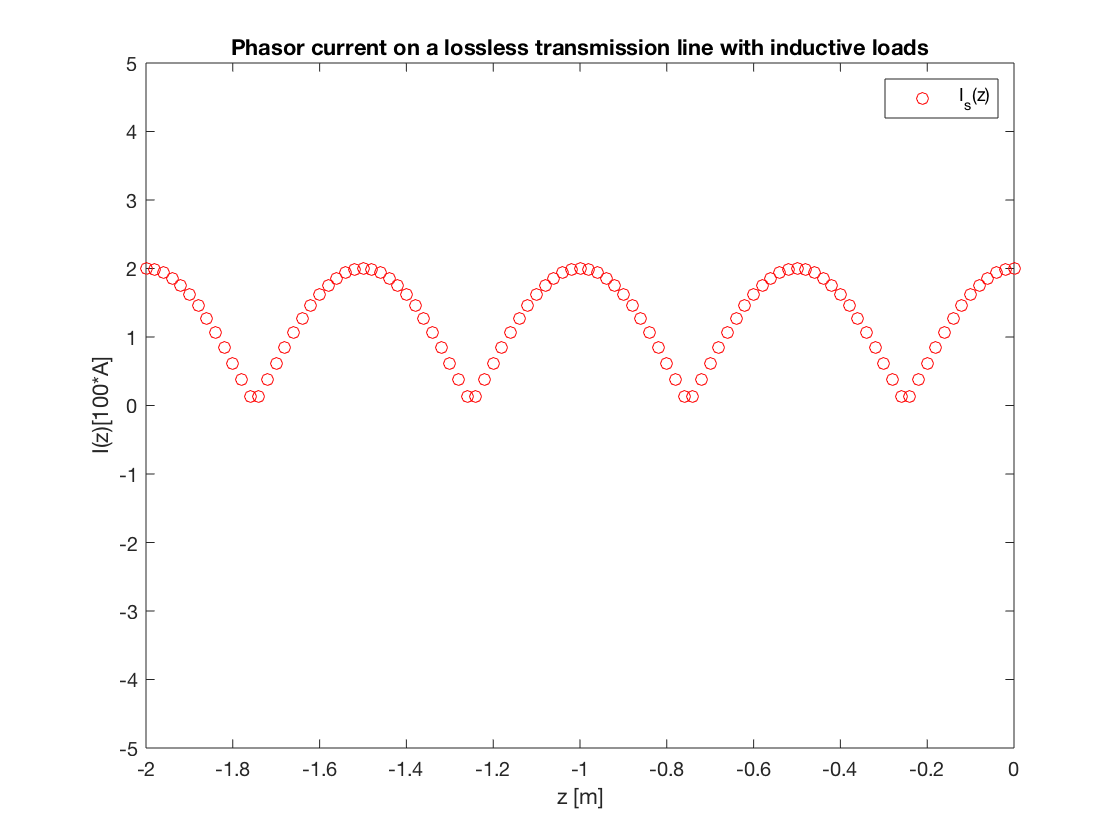

plot(z,Is,'ro');
xlabel('z [m]');
ylabel('I(z)[100*A]');
title('Phasor current on a lossless transmission line with inductive loads');
legend('I_s(z)');
axis([-2 0 -5 5]);

function [Vs,Is] = linephasor(V0,GAMMA,gamma,Z0,z)
Vs = (V0)*exp(-gamma*z) - GAMMA*(V0)*exp(gamma*z); 
Is = (V0/Z0)*exp(-gamma*z) - GAMMA*(V0/Z0)*exp(gamma*z); 
end
